# Opgave1 - M3NUM1 E15 Ordinær eksamen

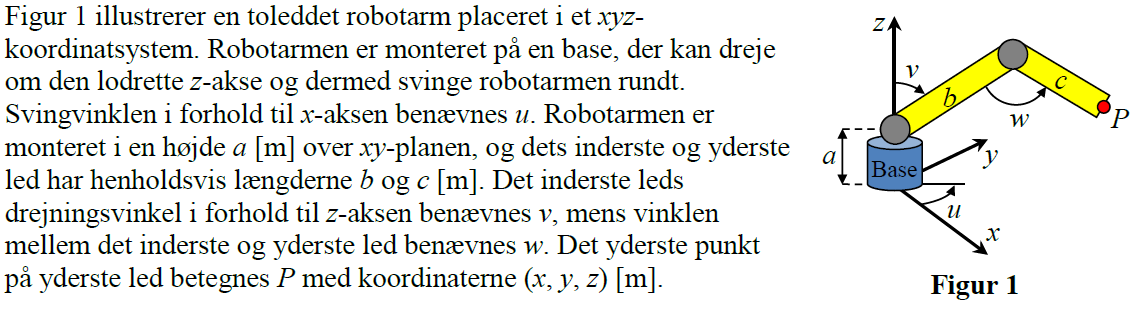

## a)

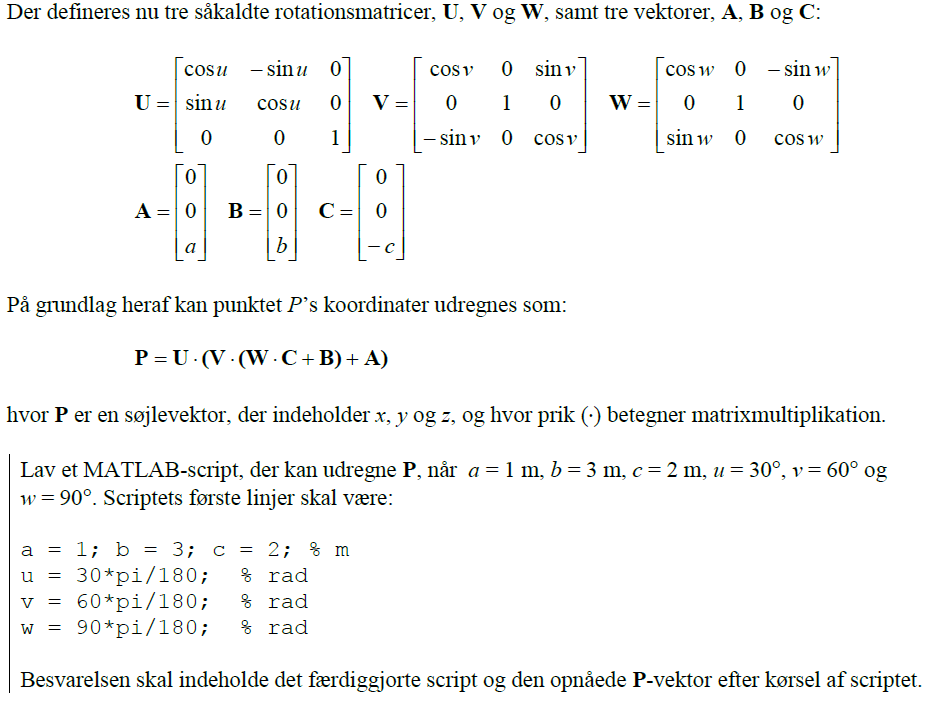

a = 1; b = 3; c = 2; % m
u = 30*pi/180; % rad
v = 60*pi/180; % rad
w = 90*pi/180; % rad

%Vi opskriver matricerne
U = [cos(u) -sin(u) 0
    sin(u) cos(u) 0
    0 0 1];

V = [cos(v) 0 sin(v)
    0 1 0
    -sin(v) 0 cos(v)];

W = [cos(w) 0 -sin(w)
    0 1 0
    sin(w) 0 cos(w)];

%Vi opskriver vektorene
A = [0; 0; a];

B = [0; 0; b];

C = [0; 0; -c];

%Der udregnes hvor resultatet bliver en vektor
P = U * (V * (W * C + B) + A)

P =     3.1160
    1.7990
    0.7679


## b)

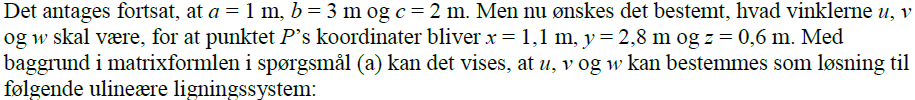

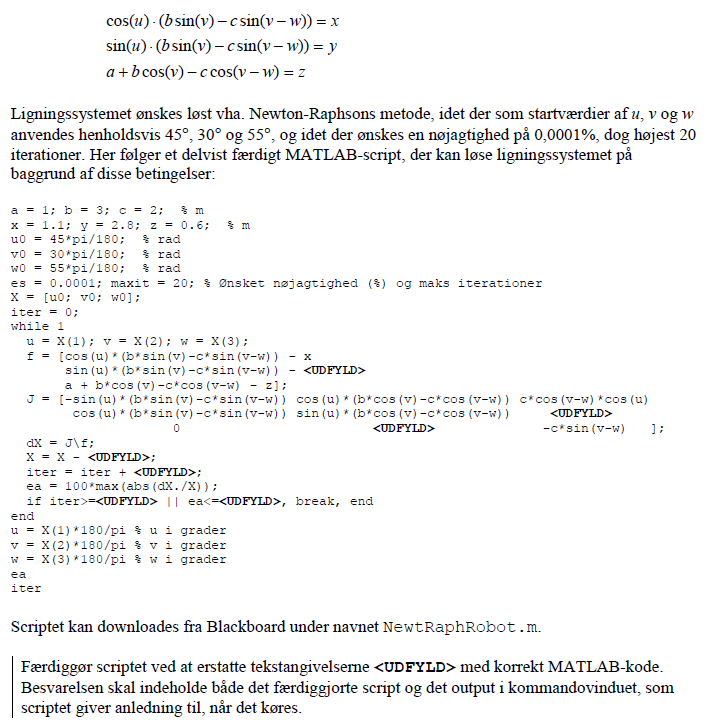

a = 1; b = 3; c = 2; % m
x = 1.1; y = 2.8; z = 0.6; % m
u0 = 45*pi/180; % rad
v0 = 30*pi/180; % rad
w0 = 55*pi/180; % rad
es = 0.0001; maxit = 20; % Ønsket nøjagtighed (%) og maks iterationer
X = [u0; v0; w0];
iter = 0;
while 1 
    u = X(1); v = X(2); w = X(3);

    f = [cos(u)*(b*sin(v)-c*sin(v-w)) - x %resultatet af hver ligning sættes = 0
        sin(u)*(b*sin(v)-c*sin(v-w)) - y
        a + b*cos(v)-c*cos(v-w) - z];

    J = [-sin(u)*(b*sin(v)-c*sin(v-w)) cos(u)*(b*cos(v)-c*cos(v-w)) c*cos(v-w)*cos(u) 
        cos(u)*(b*sin(v)-c*sin(v-w)) sin(u)*(b*cos(v)-c*cos(v-w)) <UDFYLD
        0 <UDFYLD> -c*sin(v-w) ];

    dX = J\f;
    X = X - <UDFYLD>;
    iter = iter + 1;
    ea = 100*max(abs(dX./X));
    if iter>=20 || ea<=0.0001/100, break, end
end
u = X(1)*180/pi % u i grader
v = X(2)*180/pi % v i grader
w = X(3)*180/pi % w i grader
ea
iter
Scriptet

# Opgave 4 - M3NUM1 F16 Ordinær eksamen

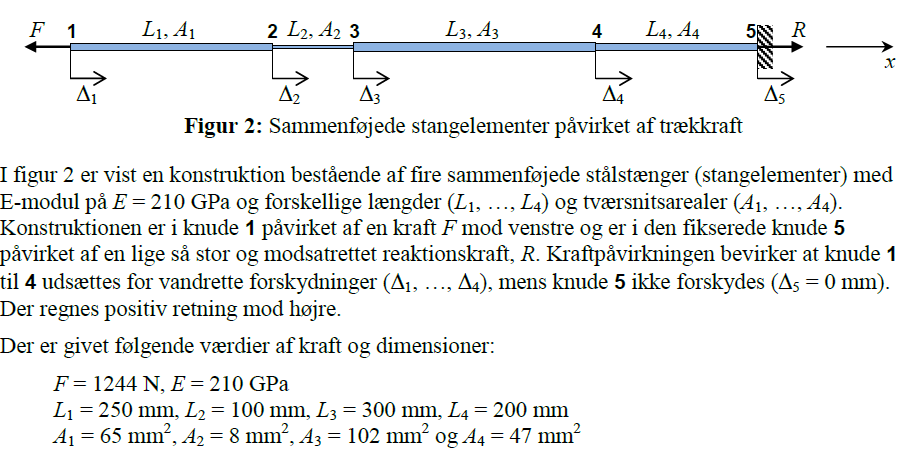

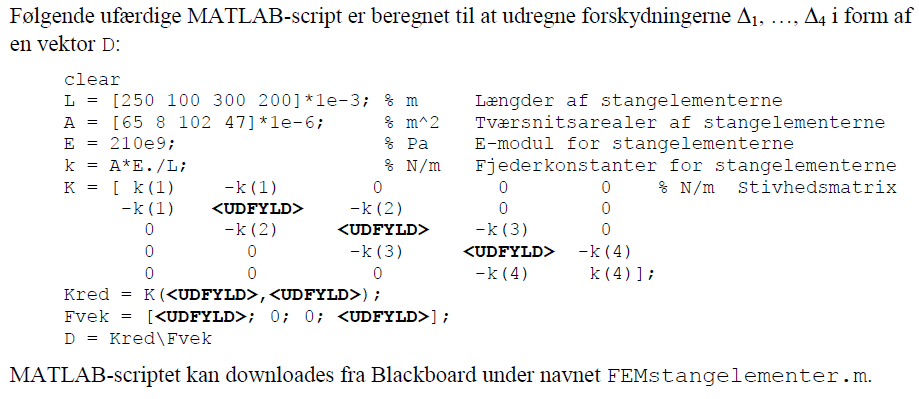

## a)

## b)

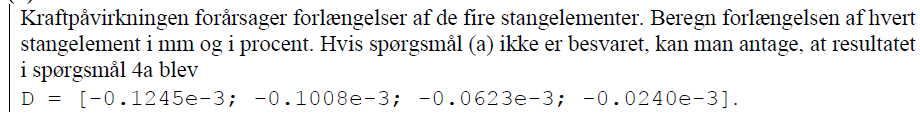

# Opgave 5 - M3NUM1 E18 Ordinær eksamen

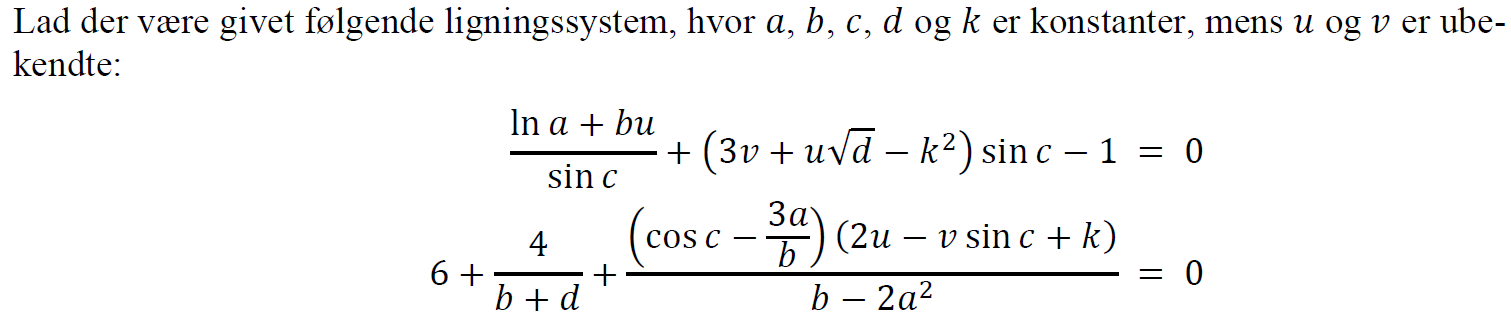

## 5a)

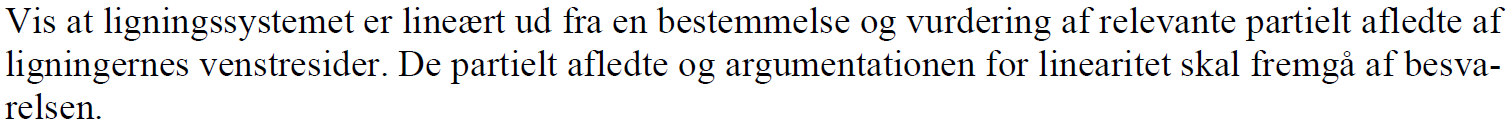

## 5b)